# **IO135 - Inter-Module Synchronization Loopback**

The IO135 I/O module is a fast, simultaneous-sampling, 16-bit analog input and output module, complete with dedicated Simulink® driver blocks.

This example demonstrates the communication between the 3 inputs and outputs present on the IO135, using DMA (Direct Memory Access) and the Inter-Module Synchronization feature. The model is triggered by the IO135 DMA interrupt block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with two IO135 I/O modules installed

- Connector cable from the I/O module to the terminal boards

- 2 50-pin terminal boards with jumper wires

### Test Setup

Connect the IO135 modules with the P3 cable to the terminal boards. On the terminal board of the analog I/O module, connect the positive (+) pins of analog inputs 24, 31 and 32 to the pins of analog outputs 1, 2 and 9, and connect the negative (-) pins of the analog inputs to GND.

#### Rear I/O Configuration:

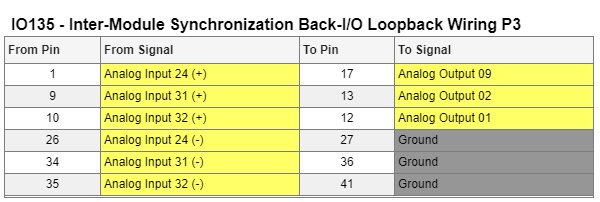

Finally, if you are using the front connection configuration, you will need to connect both terminal boards together. By connecting Digital 1 with the other Digital 1 on the second terminal board. Repeat this with Digital 3 and Digital 5 too. Check the pin wiring images below for a graphical explanation.

#### Front I/O Configuration:

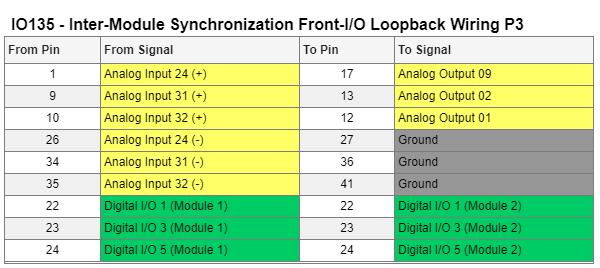

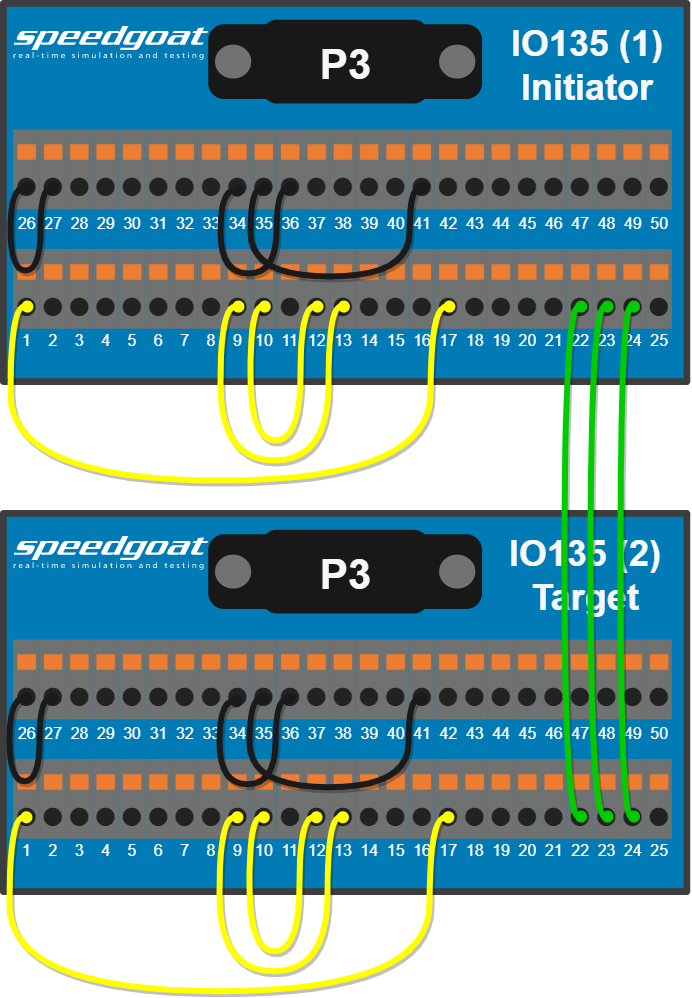

[IO135 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_pin_mapping)

## Model Description

The Simulink model features the IO135 Setup, Analog Input, Analog Output, Digital Input and Digital Output blocks. Analog inputs and outputs as well as digital inputs and outputs are enabled in the Setup block. Furthermore, the model features a Speedgoat Interrupt Setup block, configured as the model trigger. If you wish to reuse the example in a larger Simulink Model, consider placing the blocks into a function-triggered subsystem and configuring the Interrupt Setup block accordingly. Additionally, in this example, the Inter-Module Synchronization is enabled. This ensures that the analog inputs and/or outputs are synchronized.

## Initialize and Open the Simulink model

Open the Simulink model and choose your appropriate connection, by commenting out the unwanted configuration block.

 
% Open Simulink model
modelName = 'sgMdl_IO135_InterModuleSync_Loopback';
open_system(modelName);

% Define model parameters
frameSize = 10; 
clockDivider = 2000;

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Start the real-time application and open the SDI-Viewer
stoptime = 5; % Simulation length [s]
numsignals = 6; % Number of signals to be viewed in the SDI

Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;

tg.setStopTime(stoptime);
tg.start;
pause(6);

runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).convertToFrames; % Collect all frames and put them into one signal
    sigsobj(k).Checked = 1; % Plot each signal in SDI
end

Simulink.sdi.setSubplotLimits(1, 1, "AllRange", [stoptime-2, stoptime-1.95, -2, 2]);

### Check the Results

The output is then visible in the Simulink Data Inspector (SDI). You should see 6 sine waves, like in the image below:

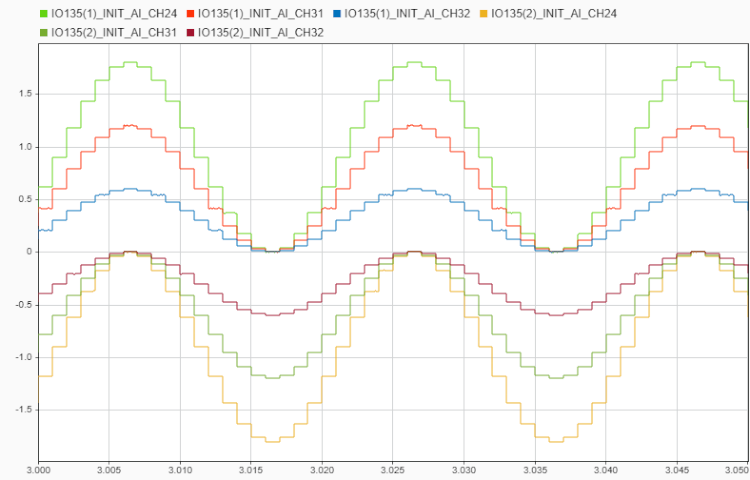

The upper three sines are the signals from the first module (initiator) analog input block. The other three sine waves are from the second module (target). When you add additional modules the sine waves will be overlapping over the three waves at the bottom.

An important note when using the inter-module synchronization is, that all the signals should vary on the time axis.

## Additional References

- [IO135 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io135)